new_env(7);

zred = 0

CLUSTER = 'CL7'

units;

r500=get_rvir(500);
r200=get_rvir(200);

boxx=4;
rho=RHOG(boxx);

global hub

tmp=T(boxx);
pre=rho.*tmp;
rhoSphere=cart2sphere(rho);
tmpSphere=cart2sphere(tmp);

## calculate median and average

len=length(rhoSphere);
rhoMean=zeros(1,len);
rhoMed=rhoMean;
rSum=rhoMean;

tmpMean=zeros(1,len);
tmpMed=tmpMean;
tSum=tmpMean;
for i=1:len
    arr=rhoSphere(i,:,:);
    arr=reshape(arr,[numel(arr) 1]);
   
    rhoMean(i)=mean(arr);
    rhoMed(i)=median(arr);
 
    arr=tmpSphere(i,:,:);
    arr=reshape(arr,[numel(arr) 1]);
   
    tmpMean(i)=mean(arr);
    tmpMed(i)=median(arr);
 
end

bin=boxx/hub/2/len;
rOut=(1:len).*bin;
rIn=rOut-bin;
rb=0.5.*(rIn+rOut);
shellVol=4*pi/3*(rOut.^3-rIn.^3);

[rhoProf,~]= read_RHO_Profiles(rb);
rhoProf2= MAKE_PROFILE_FROM_CUBE_DENSE(rho);

tmpProf= read_T_Profile(rb);
tmpProf2= MAKE_PROFILE_FROM_CUBE_DENSE(tmp);

## plot \rho profile

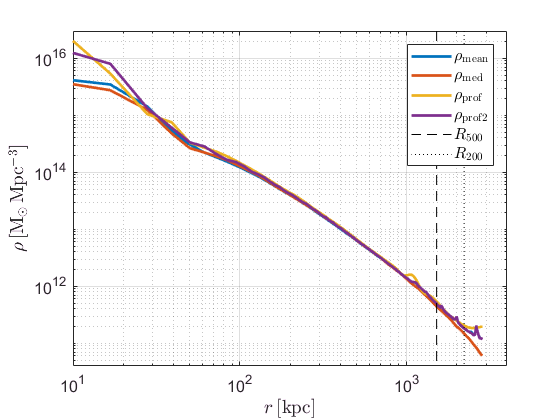


figure

h=[];
rbk=rb.*1000;
h(1)=loglog(rbk,rhoMean,'linewidth',2,...
    'DisplayName','$\rho_\mathrm{mean}$');
hold on
h(2)=loglog(rbk,rhoMed,'linewidth',2,...
    'DisplayName','$\rho_\mathrm{med}$');
h(3)=loglog(rbk,rhoProf,'linewidth',2,...
    'DisplayName','$\rho_\mathrm{prof}$');
h(4)=loglog(rbk,rhoProf2,'linewidth',2,...
    'DisplayName','$\rho_\mathrm{prof2}$');
h(5)=loglog(r500.*1000.*[1 1],[1 1e20]','--k',...
    'DisplayName','$R_{500}$');

h(6)=loglog(r200.*1000.*[1 1],[1 1e20]',':k',...
    'DisplayName','$R_{200}$');
hl=legend(h);
set(hl,'Interpreter','latex','Fontsize',12)
set(gca,'fontsize',12);
xlabelmine('$r\,[\mathrm{kpc}]$'); 
ylabelmine('$\rho\,[\mathrm{M_\odot\,Mpc^{-3}}]$');
xlim([10 4000])
ylim([4e10 3e16])
grid

## write to file

global DEFAULT_PRINTOUT_DIR
global CLUSTER
fname=[DEFAULT_PRINTOUT_DIR '/' CLUSTER '_rhoMedian_b4.txt'];
fid=fopen(fname,'w');

arr=cat(1,rb,rhoMed.*(Units.Ms./Units.Mpc^3)./(Units.muMass*Units.mp));


fprintf(fid,'%12.5e %12.5e \n',arr)

ans = 6912


fclose(fid)

ans = 0

## plot T profile

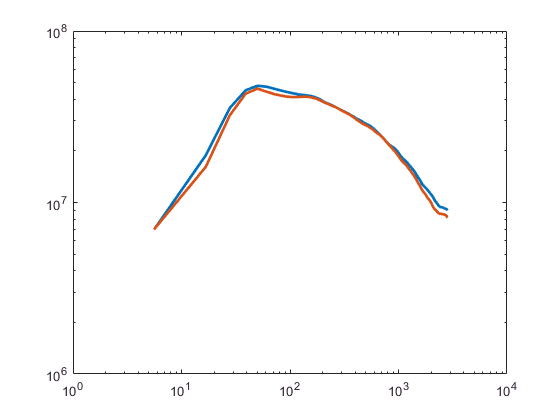


figure

h=[];
rbk=rb.*1000;
h(1)=loglog(rbk,tmpMean,'linewidth',2,...
    'DisplayName','$T_\mathrm{mean}$');
hold on
h(2)=loglog(rbk,tmpMed,'linewidth',2,...
    'DisplayName','$T_\mathrm{med}$');

h(3)=loglog(rbk,tmpProf,'linewidth',2,...
    'DisplayName','$T_\mathrm{prof}$');

Undefined function or variable 'tmpProf'.

h(4)=loglog(rbk,tmpProf2,'linewidth',2,...
    'DisplayName','$T_\mathrm{prof2}$');
h(5)=loglog(r500.*1000.*[1 1],[1 1e20]','--k',...
    'DisplayName','$R_{500}$');

h(6)=loglog(r200.*1000.*[1 1],[1 1e20]',':k',...
    'DisplayName','$R_{200}$');
hl=legend(h);
set(hl,'Interpreter','latex','Fontsize',12)
set(gca,'fontsize',12);
xlabelmine('$r\,[\mathrm{kpc}]$'); 
ylabelmine('$T\,[\mathrm{K}]$');
xlim([10 4000]);
ylim([5e6 1e8]);
grid

## write to file

global DEFAULT_PRINTOUT_DIR
global CLUSTER
fname=[DEFAULT_PRINTOUT_DIR '/' CLUSTER '_tmpMedian_b4.txt'];
fid=fopen(fname,'w');

arr=cat(1,rb,tmpMed);


fprintf(fid,'%12.5e %12.5e \n',arr)

ans = 6912


fclose(fid)

ans = 0